clear;
N1 = 40;
a1 = 1;
d1 = -0.01;
xbar1 = 1;
eps1 = 3;
gamma_2_1 = 10^-2;
gamma_1_1 = 0;

L_eps_regularised_grad_lambda_1= @(u_var) L_eps_regularised_gradient(u_var, N1, a1, d1, xbar1, eps1, gamma_2_1, gamma_1_1);
L_eps_regularised_lambda_1 = @(u_var) L_eps_regularised(u_var, N1, a1, d1, xbar1, eps1, gamma_2_1, gamma_1_1);
u1 = backtracking(L_eps_regularised_lambda_1, L_eps_regularised_grad_lambda_1, ones(N1,1), 2, 0.5, 0.5, 10^-3);

A1 = genA(d1,a1,N1);
b1 = genb(xbar1, a1, N1);
x1 = get_x(A1, u1, b1);

N2 = 40;
a2 = 1;
d2 = -0.01;
xbar2 = 1;
eps2 = 3;
gamma_2_2 = 0;
gamma_1_2 = 10^-2;

L_eps_regularised_grad_lambda_2 = @(u_var) L_eps_regularised_gradient(u_var, N2, a2, d2, xbar2, eps2, gamma_2_2, gamma_1_2);
L_eps_regularised_lambda_2 = @(u_var) L_eps_regularised(u_var, N2, a2, d2, xbar2, eps2, gamma_2_2, gamma_1_2);
u2 = backtracking(L_eps_regularised_lambda_2, L_eps_regularised_grad_lambda_2, ones(N2,1), 1, 0.44, 0.5, 10^-3);

A2 = genA(d2, a2, N2);
b2 = genb(xbar2, a2, N2);
x2 = get_x(A2, u2, b2);

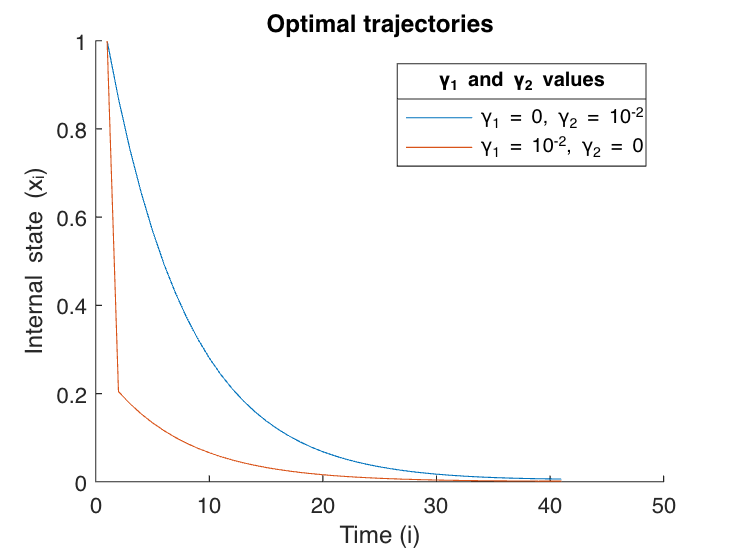

clf
hold on
plot([xbar1 xbar2;x1 x2])
hold off
title("Optimal trajectories")
leg = legend("\gamma_1 = 0, \gamma_2 = 10^{-2}", "\gamma_1 = 10^{-2}, \gamma_2 = 0", "Location", "best");
title(leg, "\gamma_1 and \gamma_2 values")
xlabel("Time (i)")
ylabel("Internal state (x_i)");

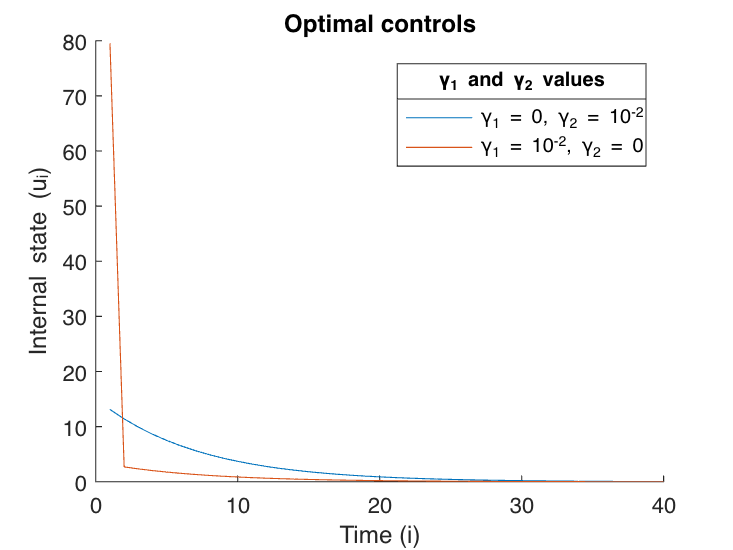

clf
hold on
plot([u1 u2])
hold off
title("Optimal controls")
leg = legend("\gamma_1 = 0, \gamma_2 = 10^{-2}", "\gamma_1 = 10^{-2}, \gamma_2 = 0", "Location", "best");
title(leg, "\gamma_1 and \gamma_2 values")
xlabel("Time (i)")
ylabel("Internal state (u_i)");